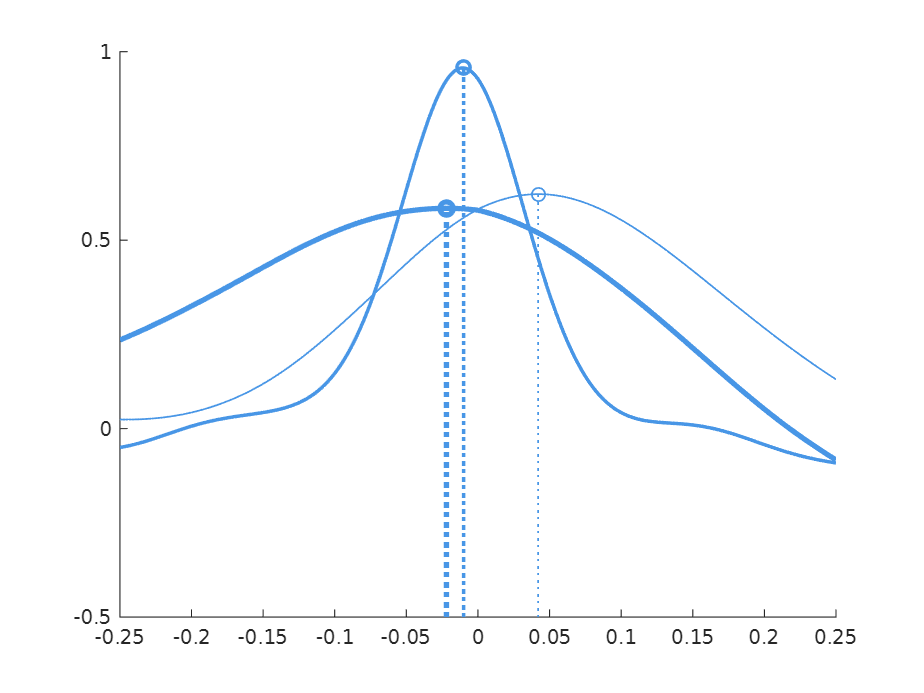

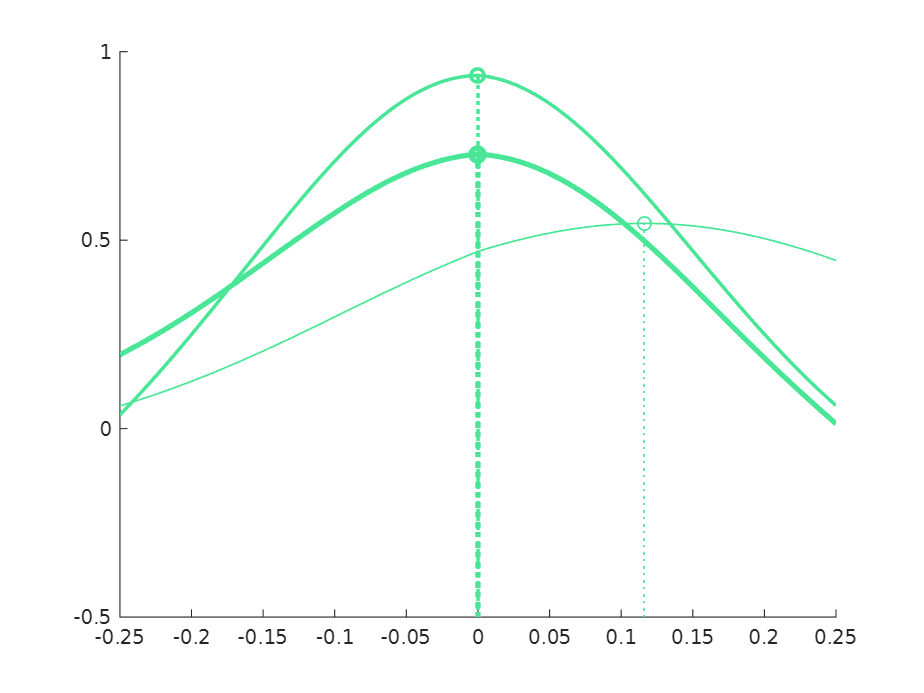


xcor     = cell(3, 2);
lags     = cell(3, 2);
cor      = zeros(3, 2);
xcor_max = zeros(3, 2);
lag_max  = zeros(3, 2);
div      = zeros(3, 2);

for j = 1:2

    figure(); hold on;

    for i = 1:3

        hd_chemo   = obj.HDSortedChemo{i, j};
        hd_control = obj.HDSortedControl{i, j};
        hd_chemo_pdf   = ksdensity(hd_chemo,   obj.Bins.HoldDuration, 'Function', 'pdf');
        hd_control_pdf = ksdensity(hd_control, obj.Bins.HoldDuration, 'Function', 'pdf');

        div(i, j) = cal_div_kl(hd_chemo_pdf, hd_control_pdf);

        cor(i, j) = corr(hd_chemo_pdf', hd_control_pdf');

        [xcor{i, j}, lags{i, j}] = xcorr(zscore(hd_chemo_pdf), zscore(hd_control_pdf), 0.25 / obj.Bins.width);
        xcor{i, j} = xcor{i, j} / (length(hd_control_pdf)-1);

        [xcor_max(i, j), id_max] = max(xcor{i, j});
        lag_max(i, j) = lags{i, j}(id_max) * obj.Bins.width;

        plot(lags{i, j}*obj.Bins.width, xcor{i, j}, 'LineWidth', 0.8*i, 'Color', GPSColor.("Port"+obj.Ports(j)))
        plot([lag_max(i, j) lag_max(i, j)], [-.5 xcor_max(i, j)], 'LineStyle', ':', 'LineWidth', 0.8*i, 'Color', GPSColor.("Port"+obj.Ports(j)))
        scatter(lag_max(i, j), xcor_max(i, j), 36, GPSColor.("Port"+obj.Ports(j)), 'LineWidth', 0.8*i, 'Marker', 'o')

    end
    
    ylim([-0.5 1])

end

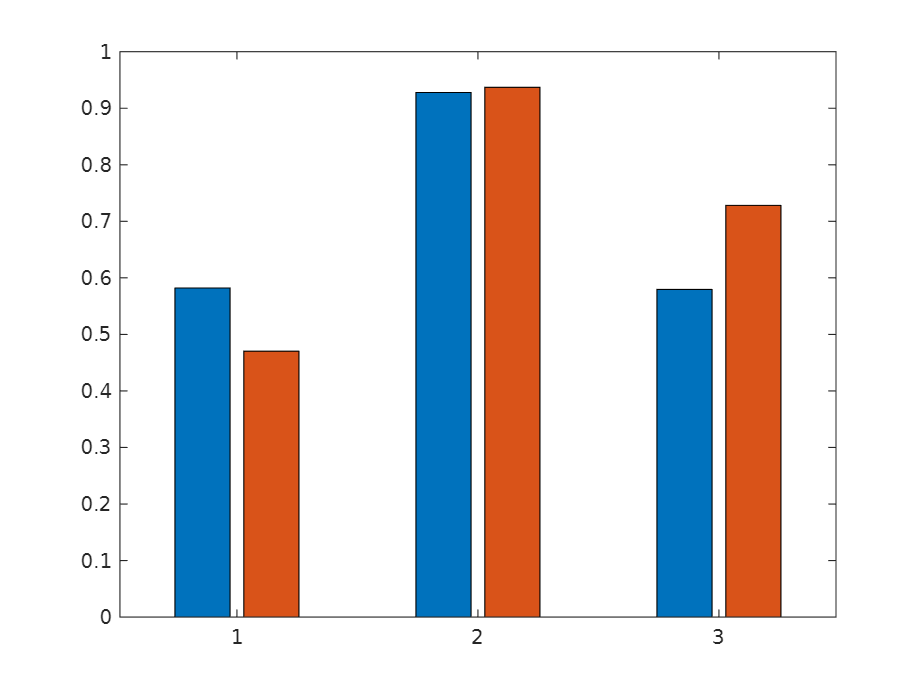


figure();
bar([cor(:, 1) cor(:, 2)])

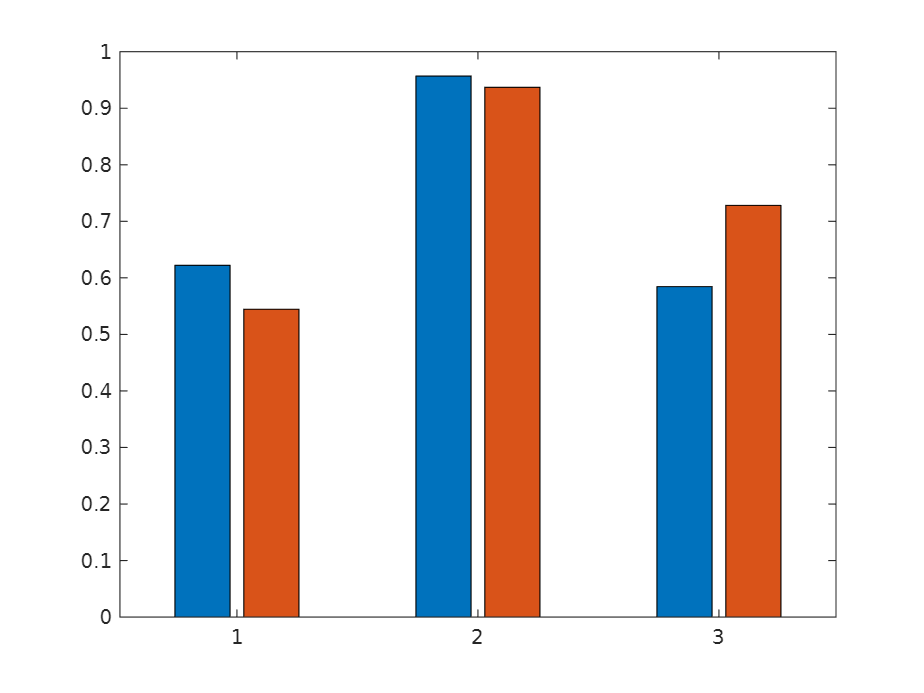


figure();
bar([xcor_max(:, 1) xcor_max(:, 2)])

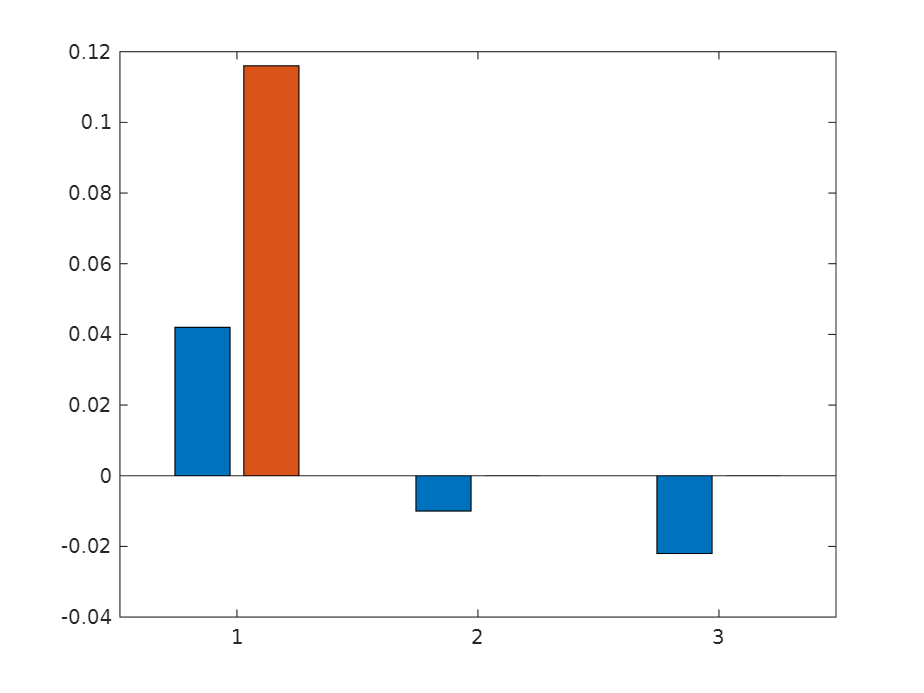


figure();
bar([lag_max(:, 1) lag_max(:, 2)])

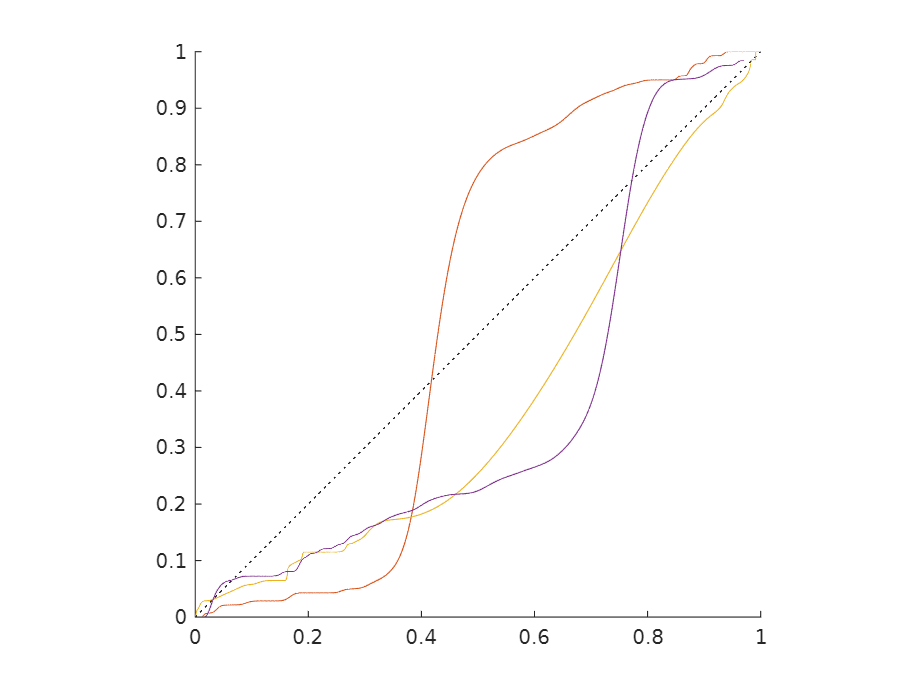

figure(); hold on;
plot([0 1], [0 1], ':k');

for i = 1:3

    hd_chemo   = obj.HDSortedChemo{i, 1};
    hd_control = obj.HDSortedControl{i, 1};

    hd_chemo_cdf   = ksdensity(hd_chemo,   obj.Bins.HoldDuration, 'Function', 'cdf');
    hd_control_cdf = ksdensity(hd_control, obj.Bins.HoldDuration, 'Function', 'cdf');

    plot(hd_chemo_cdf, hd_control_cdf)
    axis square

end

function div_kl = cal_div_kl(P, Q)

ind_good = P>0 & Q>0;

div_1 = sum( P(ind_good) .* (log(P(ind_good)) - log(Q(ind_good))) );
div_2 = sum( Q(ind_good) .* (log(Q(ind_good)) - log(P(ind_good))) );

div_kl = (div_1 + div_2) / 2;

end